# Bicycle Model

The kinematic model of the bicycle can be defined as follows:

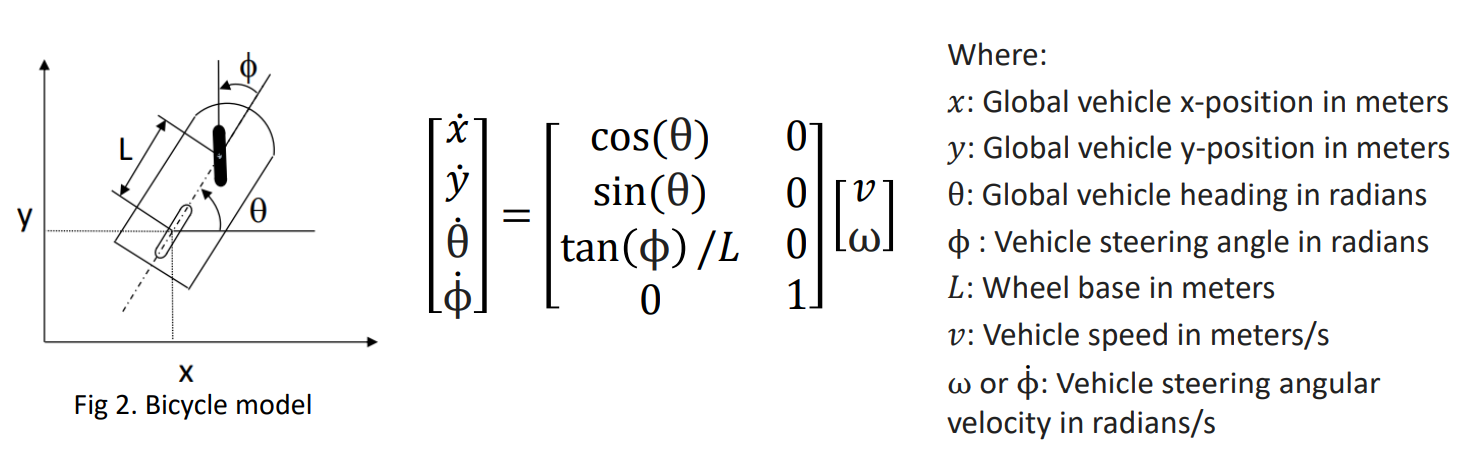

Anyway since the stearing angle $\phi$can be directly controlled, the kinematic equation can be further simplified:

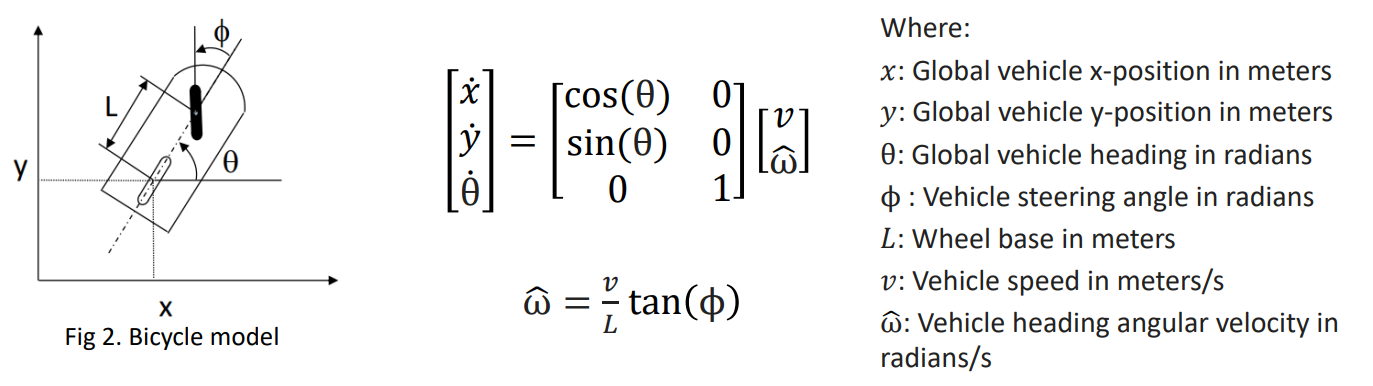

As we can see the kinematic model is very similar to the *unicycle *minus the definition of $\hat \omega$*.*

## Part 1: Custom Bicycle Kinematic Model

Here we use a function `bicycle``,` used to implement a simplified bicycle kinematics model. The model describes the vehicle's state (position x, y, and orientation θ) and computes its derivatives as follows:

- **Linear velocity (**`v`**)** is set to 1 m/s.

- **Angular velocity (**$\omega$**)** is computed using the equation $\omega$ = $\frac{v \cdot \tan(\phi)}{L}$ 

where: 

- *L* (WheelBase) is 0.1 m.

- $\phi$ is set to 0.0784 rad (limited due to physical constraints).

The `ode45` function integrates these differential equations, and the resulting trajectory is plotted.

clc
clear
close all

tspan = 0:0.05:4; 
initialState = [0 0 0];

%% Part 1: Custom Bicycle Kinematic Model
[t, q] = ode45(@bicycle, tspan, initialState);

figure
plot(q(:,1), q(:,2), 'LineWidth', 2)
title('Trajectory - Custom Bicycle Kinematic Model',"Interpreter","latex")
xlabel('X Position ($m$)',"Interpreter","latex")
ylabel('Y Position ($m$)',"Interpreter","latex")
grid on

Since the simulation lasts 4 seconds, the veichle heading velocity $v$ is 1 and the vehicle stearing angular velocity is $\frac{\pi}{4}
$ rad/s at the end the vehicle travels in a semicircle.

## Part 2: MATLAB's Built-In Bicycle Kinematics

Here we use the MATLAB's built-in `bicycleKinematics` function to create a kinematic model:

- An instance of `bicycleKinematics` is created with the mode `"VehicleInputs"` and `"VehicleSpeedHeadingRate"`.

- The `WheelBase` property is set to 0.1 m.

- A function handle is used to compute the derivatives via the `derivative` method of the model.

- The system is integrated with `ode45`, and the resulting trajectory is plotted.

Both methods allow you to compare the behavior of the custom model with MATLAB’s built-in functionality.

## Part 2: Using MATLAB's bicycleKinematics

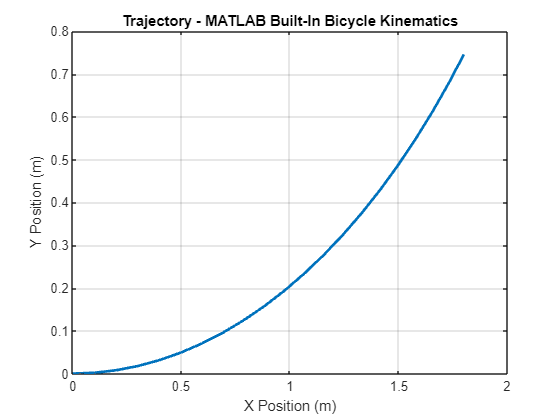

input = [1, pi/4];
bicycleModel = bicycleKinematics("VehicleInputs", "VehicleSpeedHeadingRate");
bicycleModel.WheelBase = 0.1; %Modifying the default WheelBase putting it equal L
[t, q_bicycle] = ode45(@(t, q_bicycle) derivative(bicycleModel, q_bicycle, input), tspan, initialState);

figure
plot(q_bicycle(:,1), q_bicycle(:,2), 'LineWidth', 2)
title('Trajectory - MATLAB Built-In Bicycle Kinematics',"Interpreter","latex")
xlabel('X Position ($m$)',"Interpreter","latex")
ylabel('Y Position ($m$)',"Interpreter","latex")
grid on

function dq = bicycle(t,q)
    x = q(1);
    y = q(2);
    th = q(3);

    L = 0.1; % L is the distance between the 2 wheel; Equivalent of the WheelBase  
    ph = 0.0784; %vehicle stearing angle, we cannot put for example pi/2 because than we have tan(pi/2)

    v = 1; %heading linear speed
    w = v*tan(ph)/L; %heading angular speed 

    dq = [cos(th) 0; sin(th) 0; 0 1]*[v; w]; %replaced by the derivative() function when we use the kinModel
end